Open a serial connection

if ~isempty(instrfind)
    fclose(instrfind);
    delete(instrfind);
end
s = serial('COM6','BaudRate',9600,'Parity','none');
fopen(s);


Send command 'r' and scan data

fprintf(s,'r');
for i = 1:100
    input(:,i) = fscanf(s,'%d');           
end
fclose(s);


Sort input data

raw_data = input(2,:);
maf_data = input(3,:);
iir_data = input(4,:);
fir_data = input(5,:);


Plot data

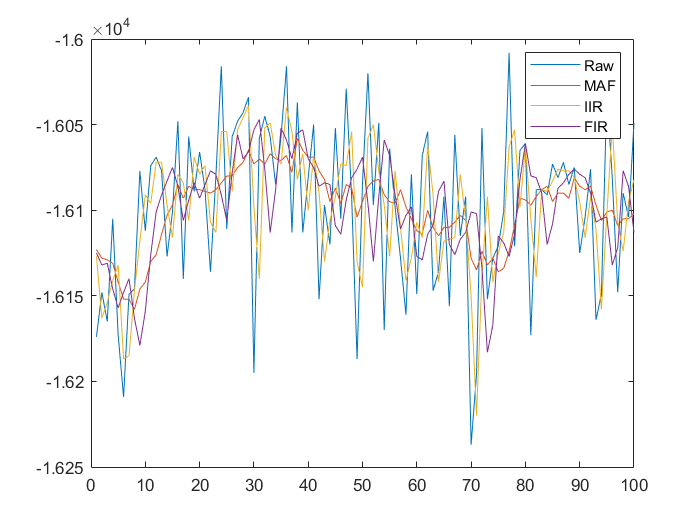

plot(raw_data);
hold on
plot(maf_data);
plot(iir_data);
plot(fir_data);
hold off
legend('Raw','MAF','IIR','FIR');